clear 
uiimport('StormEvents_2014.csv');
pause
ev=StormEvents2014

ev = 59465×23 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                   

clear StormEvents2014

groupsummary(ev,'Event_Type')

ans = 48×2 table
          Event_Type           GroupCount
    _______________________    __________

    Astronomical Low Tide           62   
    Avalanche                       42   
    Blizzard                       684   
    Coastal Flood                  106   
    Cold/Wind Chill               1146   
    Debris Flow                     62   
    Dense Fog                      794   
    Dense Smoke                      1   
    Drought                       3009   
    Dust Devil                      11   
    Dust Storm                     114   
    Excessive Heat                  83   
    Extreme Cold/Wind Chill       1821   
    Flash Flood                   3234   
    Flood                         1904   
    Freezing Fog                    65   


ev.ttime=ev.End_Date_Time-ev.Begin_Date_Time;   

ev = 59465×24 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                   

[tmax,position]=max(ev.ttime)

tmax = duration
   743:59:00


position = 227

maxEvent=ev.Event_Type(position)

maxEvent = categorical
     Drought 


ev.Property_Cost(ismissing(ev.Property_Cost))=0;
ev.Crop_Cost(ismissing(ev.Crop_Cost))=0;
ev.totalc=ev.Property_Cost+ev.Crop_Cost;
ev2=ev(ismember(ev.Event_Type,{'Coastal Flood','Flash Flood','Flood','Lakeshore Flood'}),:);
[maxc,posc]=max(ev2.totalc)

maxc = 1.1000e+09

posc = 2560

monthc=ev2.State(posc)

monthc = categorical
     MICHIGAN 


ev3=ev(ismember(ev.Month,{'August','July','June'}),:);
ev3=ev3(ev3.Event_Type=="Lightning",:);
ev31=groupsummary(ev3,"State");

ev31 = 45×2 table
       State       GroupCount
    ___________    __________

    ALABAMA             5    
    ARIZONA             6    
    ARKANSAS            9    
    CALIFORNIA          4    
    COLORADO           12    
    CONNECTICUT         2    
    DELAWARE            1    
    FLORIDA            36    
    GEORGIA             7    
    IDAHO               3    
    ILLINOIS           11    
    INDIANA             2    
    IOWA                6    
    KANSAS              1    
    KENTUCKY            6    
    LOUISIANA           7    


ev31=sortrows(ev31,'GroupCount','descend');
ev31=ev31(~ismissing(ev31.GroupCount),:)

ev31 = 45×2 table
        State         GroupCount
    ______________    __________

    FLORIDA               36    
    PENNSYLVANIA          29    
    NEW JERSEY            25    
    NEW YORK              25    
    MASSACHUSETTS         21    
    NORTH CAROLINA        19    
    COLORADO              12    
    TEXAS                 12    
    ILLINOIS              11    
    ARKANSAS               9    
    TENNESSEE              8    
    VIRGINIA               8    
    GEORGIA                7    
    LOUISIANA              7    
    MICHIGAN               7    
    WEST VIRGINIA          7    


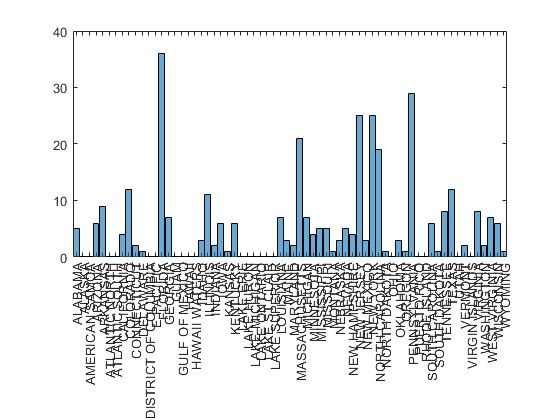

histogram(ev3.State)

ev4=ev;
ev4.Injuries_Direct(ismissing(ev.Injuries_Direct))=0;
g4=groupsummary(ev,"Event_Type","sum","Injuries_Direct");
g4=sortrows(g4,'sum_Injuries_Direct','descend')

g4 = 48×3 table
       Event_Type        GroupCount    sum_Injuries_Direct
    _________________    __________    ___________________

    Winter Weather          4615               846        
    Tornado                 1055               641        
    Thunderstorm Wind      13830               232        
    Lightning                498               156        
    Heat                     181                75        
    Wildfire                 269                38        
    Excessive Heat            83                32        
    Winter Storm            3952                27        
    Hail                    9964                23        
    Rip Current               60                19        
    Avalanche                 42                18        
    Dust Storm               114                16        
    Flash Flood             3234                16     

g4 = sortrows(g4,'GroupCount','descend')

g4 = 48×3 table
           Event_Type           GroupCount    sum_Injuries_Direct
    ________________________    __________    ___________________

    Thunderstorm Wind             13830               232        
    Hail                           9964                23        
    Winter Weather                 4615               846        
    Winter Storm                   3952                27        
    High Wind                      3253                14        
    Flash Flood                    3234                16        
    Drought                        3009                 0        
    Heavy Snow                     2637                 0        
    Flood                          1904                 4        
    Extreme Cold/Wind Chill        1821                 0        
    Heavy Rain                     1625                 4        
    Marine Thunderstorm